%% plot_tcp_trajectories.m
% TCP trajectory visualization for the chess robot system.
%
% Figure 1:
%   Local Cartesian pickup trajectory near a chess piece.
%
% Figure 2:
%   Model-based TCP path resulting from a joint-space transition
%   between two calibrated Q_HIGH region configurations.

clear; clc; close all;

%% Project path

here = fileparts(mfilename("fullpath"));
addpath(fullfile(here, "matlab"));


%% User settings

% Local pickup trajectory.
% Figure 1 uses fromSquare for the local pickup sequence.
fromSquare = "E4";
toSquare   = "F3";
pieceType  = "N";

% Joint-space transition trajectory.
% Figure 2 uses the Q_HIGH region configurations for these two squares.
transitionFromSquare = "E4";
transitionToSquare   = "A5";

% Set true if the physical board was rotated by 180 degrees.
boardRotated180 = false;

% Approximate Q_HIGH point used only in Figure 1.
% Absolute Z coordinate in the robot base frame, in metres.
qHighZ = 0.195;

% Number of samples used to visualize the joint-space transition.
nSamples = 150;

% Model-based TCP path settings for Figure 2.
% If the model TCP does not match the real setup, adjust this offset.
useTcpOffset = true;
tcpOffset_tool0 = [0.00, -0.29, 0.26];   % [x y z] in metres

% Show dashed straight line between start and end of Figure 2.
showStraightReference = true;

% Export figures to files.
exportFigures = true;
outputFolder = fullfile(here, "trajectory_figures");

%% Load calibration and generate motion data

[regions, squareCenter, boardCalib] = robotRegions();
pieceParams = robotPieceParams();

if boardRotated180
    fromSquarePhys = mapLogicalToPhysicalSquare(fromSquare, true);
    toSquarePhys   = mapLogicalToPhysicalSquare(toSquare, true);

    transitionFromSquarePhys = mapLogicalToPhysicalSquare(transitionFromSquare, true);
    transitionToSquarePhys   = mapLogicalToPhysicalSquare(transitionToSquare, true);
else
    fromSquarePhys = fromSquare;
    toSquarePhys   = toSquare;

    transitionFromSquarePhys = transitionFromSquare;
    transitionToSquarePhys   = transitionToSquare;
end

moveData = generateTransferData( ...
    fromSquarePhys, ...
    toSquarePhys, ...
    pieceType, ...
    regions, ...
    squareCenter, ...
    pieceParams);


Transfer N: E4 -> F3
FROM region: R7, baseSquare: F3
TO region:   R7, baseSquare: F3
pieceDeltaZFrom = 0.00 mm
pieceDeltaZTo = 0.00 mm
insertScale = 1.000
placeBackoff = 6.00 mm



%% Figure 1: local pickup trajectory

pQHighApprox = approximateRegionQHigh(fromSquarePhys, squareCenter, qHighZ);

pickupPoints = [
    pQHighApprox;
    moveData.P_FROM_APPROACH_HIGH(1:3);
    optionalPoint(moveData, "P_FROM_APPROACH_MID");
    moveData.P_FROM_APPROACH_LOW(1:3);
    moveData.P_FROM_INSERT_FLAT(1:3);
    moveData.P_FROM_ROTATE_LOCK(1:3);
    moveData.P_FROM_LIFT_LOCKED(1:3)
];

pickupLabels = [
    "Q high";
    "Approach high";
    optionalLabel(moveData, "P_FROM_APPROACH_MID", "Approach mid");
    "Approach low";
    "Insert";
    "Lock";
    "Lift"
];

validRows = ~any(isnan(pickupPoints), 2);
pickupPoints = pickupPoints(validRows, :);
pickupLabels = pickupLabels(validRows);

fig1 = figure("Name", "Local pickup TCP trajectory", "Color", "w");
hold on;
grid on;
axis equal;

plotBoardFromCalib(boardCalib);
addBoardLabels(boardCalib);

plot3(pickupPoints(:,1), pickupPoints(:,2), pickupPoints(:,3), ...
    "-", ...
    "LineWidth", 1.5, ...
    "DisplayName", "TCP path");

markerSize = 28;
for i = 1:size(pickupPoints, 1)
    scatter3(pickupPoints(i,1), pickupPoints(i,2), pickupPoints(i,3), ...
        markerSize, ...
        "filled", ...
        "DisplayName", pickupLabels(i));
end

setAxisLimits([pickupPoints; boardCornersFromCalib(boardCalib)], 0.08);

xlabel("X [m]");
ylabel("Y [m]");
zlabel("Z [m]");
title("TCP trajectory during local piece pickup");

legend("Location", "best");
view(-45, 35);

%% Figure 2: model-based joint-space transition between Q_HIGH points

robot = loadrobot("universalUR3", ...
    "DataFormat", "row", ...
    "Gravity", [0 0 -9.81]);

targetBody = "tool0";

qFrom = qHighForSquare(transitionFromSquarePhys, regions);
qTo   = qHighForSquare(transitionToSquarePhys, regions);

tcpPath = zeros(nSamples, 3);
sVec = linspace(0, 1, nSamples);

% Smooth interpolation parameter. The path is still joint-space based,
% but the samples are distributed more like a real motion profile.
alphaVec = 3*sVec.^2 - 2*sVec.^3;

for i = 1:nSamples
    a = alphaVec(i);
    q = (1 - a) * qFrom + a * qTo;

    tcpPath(i,:) = tcpPositionFromQ(robot, q, targetBody, ...
        useTcpOffset, tcpOffset_tool0);
end
% Anchor model-based curve to calibrated Q_HIGH positions above the board.
% This keeps the joint-space curvature but places the start/end points
% in the calibrated board coordinate frame.

pExpectedStart = approximateRegionQHigh(transitionFromSquarePhys, squareCenter, qHighZ);
pExpectedEnd   = approximateRegionQHigh(transitionToSquarePhys, squareCenter, qHighZ);

pModelStart = tcpPath(1,:);
pModelEnd   = tcpPath(end,:);

tcpPathAnchored = zeros(size(tcpPath));

for i = 1:nSamples
    a = alphaVec(i);

    modelLine = (1 - a) * pModelStart + a * pModelEnd;
    expectedLine = (1 - a) * pExpectedStart + a * pExpectedEnd;

    deviation = tcpPath(i,:) - modelLine;

    tcpPathAnchored(i,:) = expectedLine + deviation;
end

tcpPath = tcpPathAnchored;


fig2 = figure("Name", "Model-based joint-space TCP path", "Color", "w");
hold on;
grid on;
axis equal;

plotBoardFromCalib(boardCalib);
addBoardLabels(boardCalib);

plot3(tcpPath(:,1), tcpPath(:,2), tcpPath(:,3), ...
    "LineWidth", 1.8, ...
    "DisplayName", "Model-based TCP path");

scatter3(tcpPath(1,1), tcpPath(1,2), tcpPath(1,3), ...
    40, "filled", ...
    "DisplayName", "Q from high");

scatter3(tcpPath(end,1), tcpPath(end,2), tcpPath(end,3), ...
    40, "filled", ...
    "DisplayName", "Q to high");

if showStraightReference
    plot3([tcpPath(1,1), tcpPath(end,1)], ...
          [tcpPath(1,2), tcpPath(end,2)], ...
          [tcpPath(1,3), tcpPath(end,3)], ...
          "--", ...
          "LineWidth", 1.0, ...
          "DisplayName", "Straight reference");
end

setAxisLimits([tcpPath; boardCornersFromCalib(boardCalib)], 0.08);

xlabel("X [m]");
ylabel("Y [m]");
zlabel("Z [m]");
title("Model-based TCP path during joint-space transition");

legend("Location", "bestoutside");
view(-45, 35);

fprintf("Figure 2 transition: %s -> %s\n", transitionFromSquarePhys, transitionToSquarePhys);

Figure 2 transition: E4 -> A5


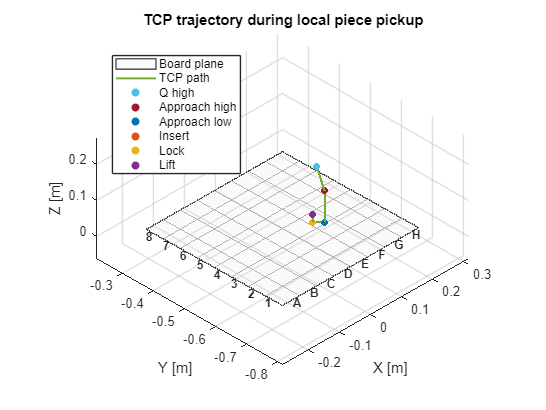

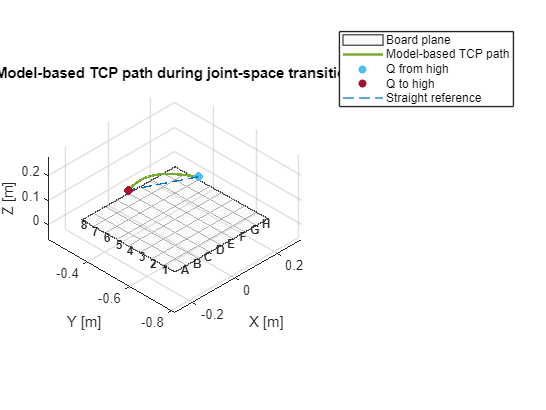

Figures exported to:
C:\Users\jpawl\AppData\Local\Temp\Editor_ofxhl\trajectory_figures



%% Export

if exportFigures
    if ~exist(outputFolder, "dir")
        mkdir(outputFolder);
    end

    exportgraphics(fig1, fullfile(outputFolder, "tcp_pickup_trajectory.png"), ...
        "Resolution", 300);

    exportgraphics(fig2, fullfile(outputFolder, "tcp_joint_transition.png"), ...
        "Resolution", 300);

    exportgraphics(fig1, fullfile(outputFolder, "tcp_pickup_trajectory.pdf"), ...
        "ContentType", "vector");

    exportgraphics(fig2, fullfile(outputFolder, "tcp_joint_transition.pdf"), ...
        "ContentType", "vector");

    fprintf("Figures exported to:\n%s\n", outputFolder);
end


%% Local helper functions

function p = optionalPoint(moveData, fieldName)
%OPTIONALPOINT Return optional Cartesian point or NaN row.

    if isfield(moveData, fieldName)
        value = moveData.(fieldName);

        if ~isempty(value) && all(isfinite(value(1:3)))
            p = value(1:3);
            return;
        end
    end

    p = [NaN NaN NaN];
end

function label = optionalLabel(moveData, fieldName, labelText)
%OPTIONALLABEL Return optional label or empty placeholder.

    if isfield(moveData, fieldName)
        value = moveData.(fieldName);

        if ~isempty(value) && all(isfinite(value(1:3)))
            label = string(labelText);
            return;
        end
    end

    label = "";
end

function plotBoardFromCalib(boardCalib)
%PLOTBOARDFROMCALIB Draw calibrated board plane from board corners.
%
% boardCalib points are expected in millimetres.

    corners = boardCornersFromCalib(boardCalib);

    cA1 = corners(1,:);
    cH1 = corners(2,:);
    cH8 = corners(3,:);
    cA8 = corners(4,:);

    X = [cA1(1), cH1(1), cH8(1), cA8(1)];
    Y = [cA1(2), cH1(2), cH8(2), cA8(2)];
    Z = [cA1(3), cH1(3), cH8(3), cA8(3)];

    patch(X, Y, Z, ...
        [0.90 0.90 0.90], ...
        "FaceAlpha", 0.18, ...
        "EdgeColor", [0.25 0.25 0.25], ...
        "LineWidth", 1.0, ...
        "DisplayName", "Board plane");

    % Draw 8x8 grid.
    for i = 0:8
        s = i / 8;

        p1 = (1-s) * cA1 + s * cA8;
        p2 = (1-s) * cH1 + s * cH8;

        plot3([p1(1), p2(1)], ...
              [p1(2), p2(2)], ...
              [p1(3), p2(3)], ...
              "Color", [0.70 0.70 0.70], ...
              "LineWidth", 0.5, ...
              "HandleVisibility", "off");

        p3 = (1-s) * cA1 + s * cH1;
        p4 = (1-s) * cA8 + s * cH8;

        plot3([p3(1), p4(1)], ...
              [p3(2), p4(2)], ...
              [p3(3), p4(3)], ...
              "Color", [0.70 0.70 0.70], ...
              "LineWidth", 0.5, ...
              "HandleVisibility", "off");
    end
end

function corners = boardCornersFromCalib(boardCalib)
%BOARDCORNERSFROMCALIB Return board outer corners in metres.
%
% Output order:
%   A1 corner
%   H1 corner
%   H8 corner
%   A8 corner

    cA1 = boardCalib.P_BOARD_A1_CORNER / 1000;
    cH1 = boardCalib.P_BOARD_H1_CORNER / 1000;
    cA8 = boardCalib.P_BOARD_A8_CORNER / 1000;
    cH8 = boardCalib.P_BOARD_H8_CORNER / 1000;

    corners = [cA1; cH1; cH8; cA8];
end

function addBoardLabels(boardCalib)
%ADDBOARDLABELS Add file/rank labels to two board edges.

    corners = boardCornersFromCalib(boardCalib);

    cA1 = corners(1,:);
    cH1 = corners(2,:);
    cH8 = corners(3,:);
    cA8 = corners(4,:);

    fileStep = (cH1 - cA1) / 8;
    rankStep = (cA8 - cA1) / 8;

    fileLabelOffset = -0.35 * rankStep;
    rankLabelOffset = -0.35 * fileStep;

    zOffset = [0 0 0.002];

    files = ["A","B","C","D","E","F","G","H"];
    ranks = ["1","2","3","4","5","6","7","8"];

    % File labels along A1-H1 edge.
    for i = 0:7
        p = cA1 + (i + 0.5) * fileStep + fileLabelOffset + zOffset;

        text(p(1), p(2), p(3), files(i+1), ...
            "HorizontalAlignment", "center", ...
            "VerticalAlignment", "middle", ...
            "FontSize", 9, ...
            "FontWeight", "bold", ...
            "Color", [0.15 0.15 0.15], ...
            "HandleVisibility", "off");
    end

    % Rank labels along A1-A8 edge.
    for i = 0:7
        p = cA1 + (i + 0.5) * rankStep + rankLabelOffset + zOffset;

        text(p(1), p(2), p(3), ranks(i+1), ...
            "HorizontalAlignment", "center", ...
            "VerticalAlignment", "middle", ...
            "FontSize", 9, ...
            "FontWeight", "bold", ...
            "Color", [0.15 0.15 0.15], ...
            "HandleVisibility", "off");
    end

    % Avoid unused variable warning in some MATLAB versions.
    %#ok<NASGU>
    cH8 = cH8;
end

function setAxisLimits(points, margin)
%SETAXISLIMITS Set equal 3D axis limits around a set of points.

    xmin = min(points(:,1)); xmax = max(points(:,1));
    ymin = min(points(:,2)); ymax = max(points(:,2));
    zmin = min(points(:,3)); zmax = max(points(:,3));

    xlim([xmin - margin, xmax + margin]);
    ylim([ymin - margin, ymax + margin]);
    zlim([zmin - margin, zmax + margin]);
end

function pTcp = tcpPositionFromQ(robot, q, targetBody, useTcpOffset, tcpOffset_tool0)
%TCPPOSITIONFROMQ Return TCP position for a given joint vector.

    T_tool0 = getTransform(robot, q, targetBody);

    if useTcpOffset
        T_tcp = T_tool0 * trvec2tform(tcpOffset_tool0);
    else
        T_tcp = T_tool0;
    end

    pTcp = tform2trvec(T_tcp);
end

function pQHigh = approximateRegionQHigh(squareName, squareCenter, qHighZ)
%APPROXIMATEREGIONQHIGH Approximate Q_HIGH point at center of 2x2 region.
%
% squareName is a physical chess square, e.g. "G1".
% squareCenter returns square centers in millimetres.
% qHighZ is absolute Z coordinate in metres.

    [fileIdx, rankIdx] = squareNameToIndex(squareName);

    baseFile = 2 * floor(fileIdx / 2);
    baseRank = 2 * floor(rankIdx / 2);

    p1 = squareCenter(baseFile,     baseRank)     / 1000;
    p2 = squareCenter(baseFile + 1, baseRank)     / 1000;
    p3 = squareCenter(baseFile,     baseRank + 1) / 1000;
    p4 = squareCenter(baseFile + 1, baseRank + 1) / 1000;

    pCenter = mean([p1; p2; p3; p4], 1);

    pQHigh = [pCenter(1), pCenter(2), qHighZ];
end

function q = qHighForSquare(squareName, regions)
%QHIGHFORSQUARE Return Q_HIGH of the 2x2 region containing squareName.

    [fileIdx, rankIdx] = squareNameToIndex(squareName);

    regionCol = floor(fileIdx / 2);
    regionRow = floor(rankIdx / 2);

    regionIdx = regionRow * 4 + regionCol + 1;

    R = regions(regionIdx);

    if isfield(R, "Q_HIGH")
        q = R.Q_HIGH;
    elseif isfield(R, "Q_deg")
        q = deg2rad(R.Q_deg);
    else
        error("Region %d does not contain Q_HIGH or Q_deg.", regionIdx);
    end

    q = reshape(q, 1, []);
end

function [fileIdx, rankIdx] = squareNameToIndex(squareName)
%SQUARENAMETOINDEX Convert square name to zero-based file/rank indices.

    squareName = upper(strtrim(string(squareName)));

    if strlength(squareName) ~= 2
        error("Invalid square name: %s", squareName);
    end

    fileChar = char(extractBetween(squareName, 1, 1));
    rankChar = char(extractBetween(squareName, 2, 2));

    fileIdx = double(fileChar) - double('A');  % A=0 ... H=7
    rankIdx = str2double(rankChar) - 1;        % 1=0 ... 8=7

    if fileIdx < 0 || fileIdx > 7 || rankIdx < 0 || rankIdx > 7
        error("Invalid square name: %s", squareName);
    end
end